# Calcualtion of Intra Hamming Distance

 (C) 2021, Juan Esteban Villegas, NYUAD

For the intra device perfoirmance we compare multiple measurements of the same device under similar test conditions, that is same temeprature, polarization, input power and uncontroled environmental conditions. This project compares as many files as defined in the structure 'files', and in general the documentation uses a total of 4 files vbeing loaded for reference. Note that measurements need to have been carried within the same spectral range and same step size.

## Read all data for TM measurements

First extract the data from the H5 files. 

folder = '..\Datasets\';
clear files
files{1} = 'AllDevices_Au1_Chips02_02_TM_user01_1705.h5';
files{2} = 'AllDevices_Au1_Chips02_02_TM_user02_1705.h5';

Load all the data

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We comapre only the drop ports in the design 3 type of devices.
dev_ind   = 13:24; file_ind = 1;
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    meas = struct.project.measurements; 
    device=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        m = meas(idx).spectra;
        device(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{file_ind} = device;
    file_ind = file_ind+1;
end

Compute Intra HD by running pairwise comaprison between the same device responses under slighlty different conditions (after scrambling and realigning polarization states and coupling).

clear('result_ref','result_shf','HDData_dev','HDData_shf');
L=0.15; mode = 'all';
               
for des = 1: 3
    HDData_d.mean =     {[],[]}; %Average and Standard deviation
    HDData_d.HDData =   {[],[],[],[]};
    HDData_d.HDData_s = {[],[],[],[]};
        
    for j = 1:4
        dev = (des-1)*4+ j;       
        data1 = dataset{1}(:,dev);   data1 = data1-max(data1);  %normalized data (in dBm)
        data2 = dataset{2}(:,dev);   data2 = data2-max(data2);  %normalized data (in dBm)
        newHD = multi_HD(lambda, [data1, data2], L);
        HDData_d.mean{1} = [ HDData_d.mean{1}; newHD.mean{1}];
        HDData_d.mean{2} = [ HDData_d.mean{2}; newHD.mean{2}];
        for k = 1:4
            HDData_d.HDData{k} = [ HDData_d.HDData{k}, newHD.HDData{k}];
            HDData_d.HDData_s{k} = [ HDData_d.HDData_s{k}, newHD.HDData_s{k}];
        end  
    end
    HDData_dev{des} = HDData_d;
end

intraAu1_dev1 = HDData_dev{1};
intraAu1_dev2 = HDData_dev{2};
intraAu1_dev3 = HDData_dev{3};

%%  distance metrics
avg = [ mean(intraAu1_dev1.mean{1}); ...
            mean(intraAu1_dev2.mean{1}); ...
            mean(intraAu1_dev3.mean{1})];

sigma = [ mean(intraAu1_dev1.mean{2}); ...
              mean(intraAu1_dev2.mean{2}); ...
              mean(intraAu1_dev2.mean{2})];

tout = display_results(avg, sigma);

Operator '>' is not supported for operands of type 'cell'.

Error in display_results (line 10)
            if avg(i,j)>1

## Plot of HD

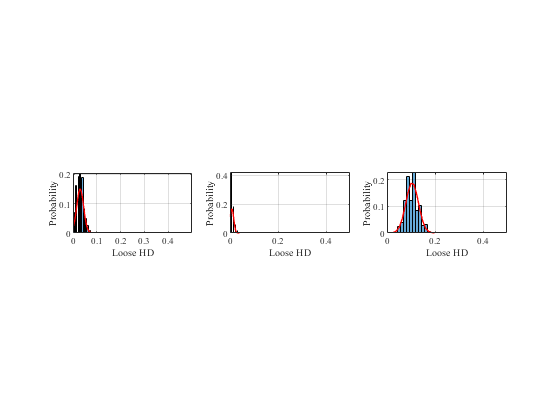

h = figure(); clf, hold off; haxis = [0,0.5];
metric = 3; %Loose HD 
device = 1;
subplot(1,3,1), 
    h = plotHD(intraAu1_dev1.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
 subplot(1,3,2), 
    h = plotHD(intraAu1_dev2.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
 subplot(1,3,3),
    h = plotHD(intraAu1_dev3.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;

## **Comparison of metrics**

We will use 'x' to mark average raw devices and 'o' to mark the responses shifted in spectrum.  This 

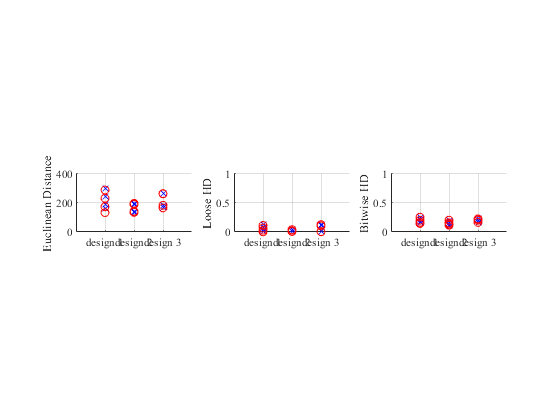

figure, clf;  labels = {'Euclinean Distance','Loose HD','Bitwise HD'};
colors = ['b','b','b']; colors_s = ['r','r','r'];
for metric = 1:3
    subplot(1,3,metric), hold on;
    for i = 1:3
        design = i;
        result_ref = HDData_dev{design}.mean{1}(:,metric+1);
        result_shf = HDData_dev{design}.mean{1}(:,metric+5);
        dev = mod(i-1,4);
        y1 = result_ref;
        y2 = result_shf;
        x1 = linspace(design,design,length(y1));
        scatter(x1,y1,'x',colors(design)); 
        scatter(x1,y2,'o',colors_s(design)); 
    end
    grid on; xlim([0,4]); 
    if metric == 1
        ylim([0,400]); 
    else
        ylim([0,1]); 
    end
    xticks(1:3); xticklabels([{'design 1'},{'design 2'},{'design 3'}]);
    set(gca,'fontname','times'); 
    ylabel(labels{metric});
    set(gca,'PlotBoxAspectRatio', [2 1 1])
end